% ASPEN Flight Data Processing and Visualization

% Loads high-rate and low-rate rocket telemetry data, synchronizes the
% data into a timetable, performs Kalman filtering and smoothing, generates plots,
% animates the rocket flight, and exports processed data.

% Main Script: ASPEN
% Author: Roger Buller

% Required Functions:
% - kalman_altitude_fusion_6dof.m
% - plot_selected_data.m
% - animate_rocket_3d_quat.m
% - quat_to_rotm.m

% Constants
sgolayPolynomialOrder = 3;
sgolayFrameLength = 21;

% Variables
xVariableName = "";
yVariableName = "";

% Menu messages
xCategoryMenuMessage = 'Select X-axis category:';
xVariableMenuMessage  = 'Select X-axis variable:';
yCategoryMenuMessage  = 'Select Y-axis category:';
yVariableMenuMessage  = 'Select Y-axis variable:';

% Directory Setup

projectDirectory = uigetdir( ...
    pwd, ...
    'Select ASPEN Project Directory');

if projectDirectory == 0

    error('No project directory selected.');

end

addpath(genpath(projectDirectory));

% Inputs
highRateFilename = input( ...
    ['Input the HR data filename with extension ' ...
     '(example: flightdata.csv): '], ...
    's');

highRateFlightData = readtable( ...
    highRateFilename, ...
    "VariableNamingRule", ...
    "preserve");

lowRateFilename = input( ...
    ['Input the LR data filename with extension ' ...
     '(example: flightdata.csv): '], ...
    's');

lowRateFlightData = readtable( ...
    lowRateFilename, ...
    "VariableNamingRule", ...
    "preserve");

% Convert tables to timetables
highRateTimetable = table2timetable( ...
    highRateFlightData, ...
    "RowTimes", ...
    'Time');

lowRateTimetable = table2timetable( ...
    lowRateFlightData, ...
    "RowTimes", ...
    'Time');

% Synchronize datasets
mergedFlightTimetable = synchronize( ...
    highRateTimetable, ...
    lowRateTimetable, ...
    'union');

filledFlightTimetable = fillmissing( ...
    mergedFlightTimetable, ...
    "nearest");

filledFlightTimetable = rmmissing(filledFlightTimetable);

% Variable category options

variableOptions.time = [ ...
    "Time"];

variableOptions.gyroAcceleration = [ ...
    "Gyro_X", ...
    "Gyro_Y", ...
    "Gyro_Z", ...
    "Accel_X", ...
    "Accel_Y", ...
    "Accel_Z"];

variableOptions.environment = [ ...
    "Temperature_(F)", ...
    "Baro_Press_(atm)"];

variableOptions.altitude = [ ...
    "Baro_Altitude_ASL_(feet)", ...
    "Baro_Altitude_AGL_(feet)", ...
    "Inertial_Altitude", ...
    "Kalman_Altitude"];

variableOptions.deviceInformation = [ ...
    "Batt_Volts", ...
    "Aux_Volts", ...
    "Current"];

variableOptions.velocity = [ ...
    "Velocity_Up", ...
    "Velocity_DR", ...
    "Velocity_CR", ...
    "Kalman_Velocity"];

variableOptions.orientation = [ ...
    "Tilt_Angle_(deg)", ...
    "Future_Angle_(deg)", ...
    "Roll_Angle_(deg)"];

variableOptions.quaternion = [ ...
    "Quat_1", ...
    "Quat_2", ...
    "Quat_3", ...
    "Quat_4"];

variableOptions.inertialPosition = [ ...
    "Inertial_DR_Position", ...
    "Inertial_CR_position"];

variableOptions.flightEvents = [ ...
    "Liftoff", ...
    "Apogee", ...
    "Burnout_Coast", ...
    "Normal_Ascent", ...
    "Apo_fired", ...
    "Main_fired"];

variableOptions.filterStates = [ ...
    "Kalman_Altitude", ...
    "Kalman_Velocity", ...
    "Kalman_Acceleration"];

menuCategories = [ ...
    "Time", ...
    "Gyro and Acceleration", ...
    "Environment", ...
    "Altitude", ...
    "Device Information", ...
    "Velocity", ...
    "Orientation", ...
    "Quaternion", ...
    "Inertial Position", ...
    "Flight Events", ...
    "Filter States"];

categoryFieldNames = { ...
    'time', ...
    'gyroAcceleration', ...
    'environment', ...
    'altitude', ...
    'deviceInformation', ...
    'velocity', ...
    'orientation', ...
    'quaternion', ...
    'inertialPosition', ...
    'flightEvents', ...
    'filterStates'};

% Select X Variable

xCategorySelection = menu( ...
    xCategoryMenuMessage, ...
    menuCategories);

xCategoryField = ...
    categoryFieldNames{xCategorySelection};

xVariableSelection = menu( ...
    xVariableMenuMessage, ...
    variableOptions.(xCategoryField));

xVariableName = ...
    variableOptions.(xCategoryField)(xVariableSelection);

% Select Y Variable

yCategorySelection = menu( ...
    yCategoryMenuMessage, ...
    menuCategories);

yCategoryField = ...
    categoryFieldNames{yCategorySelection};

yVariableSelection = menu( ...
    yVariableMenuMessage, ...
    variableOptions.(yCategoryField));

yVariableName = ...
    variableOptions.(yCategoryField)(yVariableSelection);

% Kalman Filtering
[estimatedAltitudeFeet, ...
 estimatedVelocityFeetPerSecond, ...
 estimatedAccelerationFeetPerSecond2] = ...
    kalman_altitude_fusion_6dof( ...
    filledFlightTimetable);

% Signal Smoothing
estimatedAltitudeFeet = sgolayfilt( ...
    estimatedAltitudeFeet, ...
    sgolayPolynomialOrder, ...
    sgolayFrameLength);

filledFlightTimetable.Velocity_DR = sgolayfilt( ...
    filledFlightTimetable.Velocity_DR, ...
    sgolayPolynomialOrder, ...
    sgolayFrameLength);

filledFlightTimetable.Velocity_CR = sgolayfilt( ...
    filledFlightTimetable.Velocity_CR, ...
    sgolayPolynomialOrder, ...
    sgolayFrameLength);

% Store Kalman outputs in timetable
filledFlightTimetable.Kalman_Altitude = ...
    estimatedAltitudeFeet;

filledFlightTimetable.Kalman_Velocity = ...
    estimatedVelocityFeetPerSecond;

filledFlightTimetable.Kalman_Acceleration = ...
    estimatedAccelerationFeetPerSecond2;

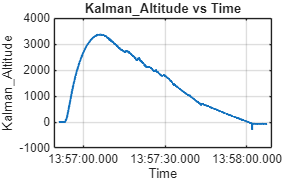

% Plotting
plot_selected_data( ...
    filledFlightTimetable, ...
    xVariableName, ...
    yVariableName);

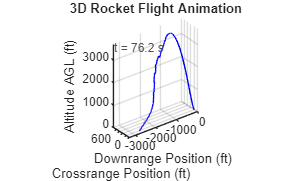

% Flight Animation
animate_rocket_3d_quat( ...
    filledFlightTimetable, ...
    estimatedAltitudeFeet);

% Export Options
exportChoice = menu( ...
    "Select export option:", ...
    "None", ...
    "Data Only", ...
    "Figures Only", ...
    "Data and Figures");

if exportChoice == 1
    return;
end

% Base filename for exported content
baseFilename = input( ...
    'Enter export base filename: ', ...
    's');

% Export Data
if exportChoice == 2 || exportChoice == 4

    exportMenuOptions = [ ...
        "Fused Altitude", ...
        "Fused Velocity", ...
        "Fused Acceleration", ...
        "All Fused Data", ...
        "Original Filled Flight Data"];

    exportSelection = menu( ...
        "Select data to export:", ...
        exportMenuOptions);

    timeSeconds = seconds( ...
        filledFlightTimetable.Time - ...
        filledFlightTimetable.Time(1));

    timeSeconds = timeSeconds(:);

    switch exportSelection

        case 1
            exportTable = table( ...
                timeSeconds, ...
                estimatedAltitudeFeet, ...
                'VariableNames', ...
                {'Time_s', 'Altitude_ft'});

        case 2
            exportTable = table( ...
                timeSeconds, ...
                estimatedVelocityFeetPerSecond, ...
                'VariableNames', ...
                {'Time_s', 'Velocity_ft_s'});

        case 3
            exportTable = table( ...
                timeSeconds, ...
                estimatedAccelerationFeetPerSecond2, ...
                'VariableNames', ...
                {'Time_s', 'Acceleration_ft_s2'});

        case 4
            exportTable = table( ...
                timeSeconds, ...
                estimatedAltitudeFeet, ...
                estimatedVelocityFeetPerSecond, ...
                estimatedAccelerationFeetPerSecond2, ...
                'VariableNames', ...
                {'Time_s', ...
                 'Altitude_ft', ...
                 'Velocity_ft_s', ...
                 'Acceleration_ft_s2'});

        case 5
            exportTable = ...
                timetable2table(filledFlightTimetable);

    end

    writetable(exportTable, [baseFilename '.csv']);

    fprintf('Data exported to %s.csv\n', baseFilename);

end

% Export Figures
if exportChoice == 3 || exportChoice == 4

    figureHandles = findall(0, 'Type', 'figure');

    if isempty(figureHandles)

        fprintf('No figures available for export.\n');

    else

        for iFigure = 1:length(figureHandles)

            currentFigure = figureHandles(iFigure);
            figureNumber = currentFigure.Number;

            exportgraphics( ...
                currentFigure, ...
                sprintf('%s_fig%d.png', ...
                baseFilename, ...
                figureNumber));

            savefig( ...
                currentFigure, ...
                sprintf('%s_fig%d.fig', ...
                baseFilename, ...
                figureNumber));

        end

        fprintf( ...
            'Exported %d figure(s).\n', ...
            length(figureHandles));

    end

end